# A unified framework for cross-sectional asset pricing using GMM

## Introduction

The aim of this Live Script is to illustrate the workings of the unified framework of asset pricing using GMM. It builds upon the main principles of Fama-MacBeth two-pass cross-sectional regressions, yet utilizes GMM to obtain standard errors that are robust to both autocorrelation, heteroskedasticity, and errors-in-variables. 

I have provided you with a function fCrossSecAnalysis() that is used to estimate and analyze a linearized consumption-based asset pricing model. I encourage you to go through it and understand how it relates to the formulas in the lecture notes. 

## Loading Kenneth French data

Go to Kenneth French data library ([http://mba.tuck.dartmouth.edu/pages/faculty/ken.french/data_library.html](http://mba.tuck.dartmouth.edu/pages/faculty/ken.french/data_library.html)) and download data on 25 portfolios sorted on size (ME) and book-to-market equity (BE/ME) ratios (also known as 25 size-value portfolios) and data on the risk-free rate and the excess market return, which you can find under the Fama-French 3-factor data. We will work with quarterly data in this example. In this case, we should compound the returns on the 25 portfolios (before subtracting the risk-free rate) and the risk-free rate, and then compute quaterly excess returns. We also compound the SMB and HML factors. Below we download already pre-processed data that runs from 1960:Q1 to 2017:Q3, and relevant returns are already subtracted the risk-free rate. 

% Housekeeping 
clear 
clc

% Loading data from mat files
load('sizeValuePortfoliosQ.mat');
load('famaFrenchFactorsQ.mat');

## Loading consumption-data 

Go to the St. Louis Fred database ([https://fred.stlouisfed.org/series/PCENDC96](https://fred.stlouisfed.org/series/PCENDC96)) and download data on quarterly real nondurable personal expecnditure (consumption). I have already computed (logarithmic) growth rates. 

% Loading data from mat file
load('logConsGrowthQ.mat');

## Setting up data

% Setting up data
SMB                     = famaFrenchFactorsQ(:,2);
HML                     = famaFrenchFactorsQ(:,3);
excessPortfolioReturns  = sizeValuePortfoliosQ;

## Estimating cross-sectional risk prices

In our formulation of the linearized CCAPM, we work with excess portfolio return. That is, we aim to estimate the following equation

$\mathbb{E}\left[R_{it+1} - R_{ft+1}\right]= \gamma_{0}  + \gamma_{c} \beta_{ic}  + \gamma_{HML}\beta_{iHML} $,

where we add the value factor of the Fama-French factors in the interest of testing for some model misspecification. 

To obtain cross-sectional asset pricing results, we use the provided function fCrossSecAnalysis(). 

% Set lag length for use in first stage and second stage (in the second stage we use nLags in case you put flagAndrews = 0) 
nLags        = 4;

% Decide as to whether 
flagAndrews  = 1;

% Decide on risk factors 
riskFactors  = [logConsGrowthQ HML];

% Run Fama-Macbeth with and without GMM standard errors 
[firstStage,secondStage] = fCrossSecAnalysis(excessPortfolioReturns,riskFactors,flagAndrews,nLags);
secondStage

secondStage = struct with fields:
         gamma: [0.0233 0.0051 0.0110]
     seGammaFM: [0.0062 0.0031 0.0039]
       tstatFM: [3.7624 1.6646 2.8506]
    seGammaGMM: [0.0095 0.0038 0.0042]
      tstatGMM: [2.4553 1.3398 2.6541]
            r2: 62.1598
           fit: [25×1 double]
          mean: [25×1 double]
          MAPE: 0.0030
          RMSE: 0.0037


On the back of this estimation, one should then make diagnostics of the model's asset pricing ability, using e.g, pricing error plots as we saw in the live script for Fama-Macbeth regressions with and without Shanken-corrected standard errors, commenting on MAPE or RMSE, and, of course, commenting on the size, sign, and significance of the risk prices (including the intercept). 

## Estimating cross-sectional risk prices in a *conditional model*

Remember that a linear factor SDF was equivalent to a $\beta$ representation. That is, $M_{t+1} = 1 - b'f_{t+1}$ implied a $\beta$ representation as 

$\mathbb{E}\left[R_{it+1} - R_{ft+1}\right]= \gamma \beta_i$,

and vice versa. Now, what if $b$ is not constant? That is, we have a conditional asset pricing model. A very popular approach to handling time-varying $b$s in the linear factor SDF is to model them as (linear) functions of something observable that is *adapted *to (contained in) the time-*t* information set. The most popular case is to use a univariate instrument $z_t$ that is supposed to capture the conditionality of $b_{t}$ and then define it as follows 

$b_{t} = g(z_t) = b_{0} +b_{1}z_t,$,

where $g(\cdot)$ is a real-valued, linear function. The neat thing about this, assuming a single factor model for simplicity, is that one obtains 


$$M_{t+1} = 1 - b_tf_{t+1} = 1 - g(z_t)f_{t+1} = 1 - b_{0}f_{t+1} -b_{1}z_tf_{t+1},$$


which is now (again) an unconditional specification but with *two* factors instead of one. This amounts to just adding the interaction between the instrument and the original factor as a new factor. For the interested student, you should consult Cochrane's book called "Asset Pricing (Revised edition)" Chapter 8, and in particular the section called "Scaled Factors: A Partial Solution". One could actually think of this as a complimentary definition of Beauty as defined in the lecture slides due to its usefulness. In the context of the current CCAPM setting, our (implied) SDF is 


$$M_{t+1} = 1 - b\tilde{c}_{t+1}$$


where $\tilde{c}_{t+1}$ denotes consumption growth. Suppose we have an instrument $z_t$ that is useful in capturing variations in $b$ over time - essentially a variable that captures the time-varying relationship between the SDF (marginal utility growth) and consumption growth. Lettau and Ludvigson (2001) has a suggestion in their paper "Resurrecting the (C)CAPM: A Cross-Sectional Test When Risk Premia Are Time-Varying" and I recommend you to consult the paper for additional details. The instrument is referred to as $cay_t$*, *measuring the consumption-to-wealth ratio in the economy. They propose, therefore, the following time-varying $b$ SDF (conditional model) 

$M_{t+1} = 1 - b_t\tilde{c}_{t+1}, \quad b_t = b_{0} + b_{1}cay_t$,

such that 

$M_{t+1} = 1 - b_{0}\tilde{c}_{t+1} -b_{1}cay_t \tilde{c}_{t+1}$.

This implies the following $\beta$ representation 

$\mathbb{E}\left[R_{it+1} - R_{ft+1}\right]= \gamma_0 +  \gamma_c\beta_{ic} + \gamma_{cay}\beta_{icay}$,

where we add the intercept for empirical reasons, as always. Again, note how we now have two factors rather than one, but the model can still be estimated using our unconditional methods. We will do this in the following. 

First, we obtain the variable $cay_t$ from Martin Lettau's personal website ([https://sites.google.com/view/martinlettau/data](https://sites.google.com/view/martinlettau/data)). Load it now. I have already made it such that it runs from 1959Q4 to 2017Q3 (we need the lagged value in order to conform with the adaptedness to $\mathcal{F}_t$. 

% Load 
load('cay.mat')

% Make instrument vector 
z    = cay(1:end-1,2); 

% Run cross-sectional analysis using the approach seen above, i.e. with an
% additional risk factor that is the interaction of z with c

% Decide on risk factors 
riskFactors  = [logConsGrowthQ logConsGrowthQ.*z];

% Run Fama-Macbeth with and without GMM standard errors 
[firstStage,secondStage] = fCrossSecAnalysis(excessPortfolioReturns,riskFactors,flagAndrews,nLags);
secondStage

secondStage = struct with fields:
         gamma: [0.0225 0.0037 2.1004e-04]
     seGammaFM: [0.0062 0.0031 9.0498e-05]
       tstatFM: [3.6503 1.1883 2.3209]
    seGammaGMM: [0.0150 0.0062 1.5265e-04]
      tstatGMM: [1.5009 0.5948 1.3759]
            r2: 27.5121
           fit: [25×1 double]
          mean: [25×1 double]
          MAPE: 0.0044
          RMSE: 0.0051


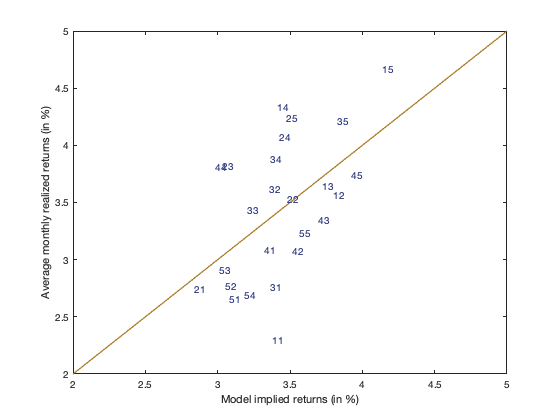

figure;
axis([2 5 2 5]);
ref = refline(1,0);
ref.Color = [166/255 118/255 29/255];
ref.LineWidth = 1.2;
xlabel('Model implied returns (in %)');
ylabel('Average monthly realized returns (in %)');
box on
labels = {'11','12','13','14','15','21','22','23','24','25',...
'31','32','33','34','35','41','42','43','44','45','51','52','53','54','55'};
hold on
text(secondStage.fit*100,secondStage.mean*100, labels,'HorizontalAlignment','center','FontSize',10,'Color',[42/255 52/255 122/255]);
text(0.3,0.6,'45\circ line','HorizontalAlignment','center','FontSize',12);
quiver(0.3,0.55,0,-0.20,0,'Color','k');
hold off

Which should be compared to how the model does without the instrument used:

% Decide on risk factors 
riskFactors  = [logConsGrowthQ];

% Run Fama-Macbeth with and without GMM standard errors 
[firstStage,secondStage] = fCrossSecAnalysis(excessPortfolioReturns,riskFactors,flagAndrews,nLags);
secondStage

secondStage = struct with fields:
         gamma: [0.0256 0.0033]
     seGammaFM: [0.0063 0.0032]
       tstatFM: [4.0671 1.0510]
    seGammaGMM: [0.0078 0.0032]
      tstatGMM: [3.2810 1.0261]
            r2: 8.0461
           fit: [25×1 double]
          mean: [25×1 double]
          MAPE: 0.0047
          RMSE: 0.0058


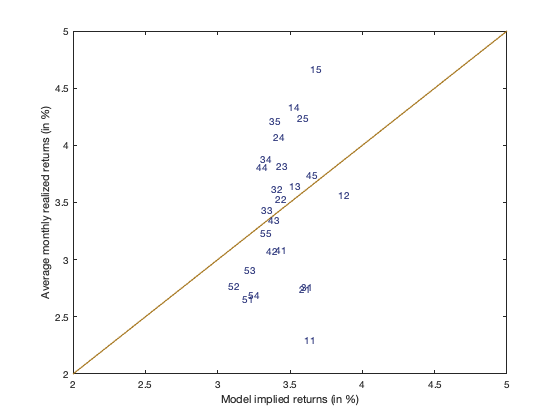

figure;
axis([2 5 2 5]);
ref = refline(1,0);
ref.Color = [166/255 118/255 29/255];
ref.LineWidth = 1.2;
xlabel('Model implied returns (in %)');
ylabel('Average monthly realized returns (in %)');
box on
labels = {'11','12','13','14','15','21','22','23','24','25',...
'31','32','33','34','35','41','42','43','44','45','51','52','53','54','55'};
hold on
text(secondStage.fit*100,secondStage.mean*100, labels,'HorizontalAlignment','center','FontSize',10,'Color',[42/255 52/255 122/255]);
text(0.3,0.6,'45\circ line','HorizontalAlignment','center','FontSize',12);
quiver(0.3,0.55,0,-0.20,0,'Color','k');
hold off